## Metabolic Modelling Introduction 

Authors : Hugues Escoffier & Maria Pires Pacheco

#### Creation of a Toy Model

**Model : **

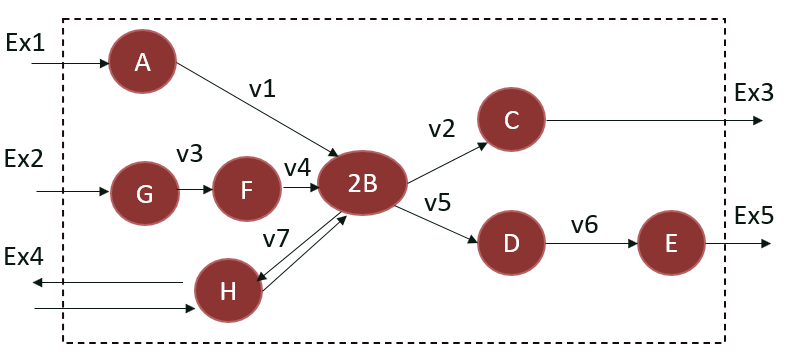

clear

%Create Model
ReactionFormulas = {'A -> 2 B','2 B -> C', 'G -> F','F -> 2 B', '2 B -> D','D -> E', ...
                    'H <=> 2 B', '-> A', '-> G', 'C ->', '<=> H', 'E ->'};
ReactionNames = {'v1','v2','v3', 'v4', 'v5', 'v6', 'v7', 'Ex1','Ex2','Ex3','Ex4','Ex5'};
GeneNames={'Gene1','Gene2','Gene3', 'Gene4', 'Gene5', 'Gene6','Gene7','GeneEx1', 'GeneEx2', 'GeneEx3', 'GeneEx4', 'GeneEx5'};
model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

Adding the following Metabolites to the model:
A[c]
B[c]
C[c]
D[c]
E[c]
F[c]
G[c]
H[c]
addMultipleReactions: Adding the following reactions to the model:
v1	A[c] 	->	2 B[c] 
v2	2 B[c] 	->	C[c] 
v3	G[c] 	->	F[c] 
v4	F[c] 	->	2 B[c] 
v5	2 B[c] 	->	D[c] 
v6	D[c] 	->	E[c] 
v7	H[c] 	<=>	2 B[c] 
Ex1		->	A[c] 
Ex2		->	G[c] 
Ex3	C[c] 	->	
Ex4		<=>	H[c] 
Ex5	E[c] 	->	


model.description = 'recon'

model = struct with fields:
           rxns: {12×1 cell}
              S: [8×12 double]
             lb: [12×1 double]
             ub: [12×1 double]
              c: [12×1 double]
           mets: {8×1 cell}
              b: [8×1 double]
          rules: {12×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [8×1 char]
     rxnGeneMat: [12×12 double]
       metNames: {8×1 cell}
     subSystems: {12×1 cell}
        grRules: {12×1 cell}
       rxnNames: {12×1 cell}
    description: 'recon'


**In the case of the Recon3D model, by convention, all exchange reactions are defined as exports and reversible. **

For example, in this model the exchange reaction ' -> G' becomes by convention 'G <=>'.

%Create Model as Recon3D
ReactionFormulas = {'A -> 2 B','2 B -> C', 'G -> F','F -> 2 B', '2 B -> D','D -> E', ...
                    'H <=> 2 B', 'A <=>', 'G <=>', 'C ->', 'H <=>', 'E ->'};
ReactionNames = {'v1','v2','v3', 'v4', 'v5', 'v6', 'v7', 'Ex1','Ex2','Ex3','Ex4','Ex5'};
GeneNames={'Gene1','Gene2','Gene3', 'Gene4', 'Gene5', 'Gene6','Gene7','GeneEx1', 'GeneEx2', 'GeneEx3', 'GeneEx4', 'GeneEx5'};
model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

Adding the following Metabolites to the model:
A[c]
B[c]
C[c]
D[c]
E[c]
F[c]
G[c]
H[c]
addMultipleReactions: Adding the following reactions to the model:
v1	A[c] 	->	2 B[c] 
v2	2 B[c] 	->	C[c] 
v3	G[c] 	->	F[c] 
v4	F[c] 	->	2 B[c] 
v5	2 B[c] 	->	D[c] 
v6	D[c] 	->	E[c] 
v7	H[c] 	<=>	2 B[c] 
Ex1	A[c] 	<=>	
Ex2	G[c] 	<=>	
Ex3	C[c] 	->	
Ex4	H[c] 	<=>	
Ex5	E[c] 	->	


model.description = 'recon'

model = struct with fields:
           rxns: {12×1 cell}
              S: [8×12 double]
             lb: [12×1 double]
             ub: [12×1 double]
              c: [12×1 double]
           mets: {8×1 cell}
              b: [8×1 double]
          rules: {12×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [8×1 char]
     rxnGeneMat: [12×12 double]
       metNames: {8×1 cell}
     subSystems: {12×1 cell}
        grRules: {12×1 cell}
       rxnNames: {12×1 cell}
    description: 'recon'


% (Facultative) Visualize the model

disp('S') ; full(model.S) %S Matrix

S


ans =     -1     0     0     0     0     0     0    -1     0     0     0     0
     2    -2     0     2    -2     0     2     0     0     0     0     0
     0     1     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     1    -1     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0    -1
     0     0     1    -1     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0    -1     0     0     0    -1     0


disp('mets') ; model.mets %Metabolites 

mets


ans = 8×1 cell array
    {'A[c]'}
    {'B[c]'}
    {'C[c]'}
    {'D[c]'}
    {'E[c]'}
    {'F[c]'}
    {'G[c]'}
    {'H[c]'}


disp('rxns') ; model.rxns %Reactions

rxns


ans = 12×1 cell array
    {'v1' }
    {'v2' }
    {'v3' }
    {'v4' }
    {'v5' }
    {'v6' }
    {'v7' }
    {'Ex1'}
    {'Ex2'}
    {'Ex3'}
    {'Ex4'}
    {'Ex5'}


disp('boundaries') ; disp([model.rxns num2cell(model.lb) num2cell(model.ub)]) %Upper & Lower boundaries for each reactions

boundaries
    {'v1' }    {[    0]}    {[1000]}
    {'v2' }    {[    0]}    {[1000]}
    {'v3' }    {[    0]}    {[1000]}
    {'v4' }    {[    0]}    {[1000]}
    {'v5' }    {[    0]}    {[1000]}
    {'v6' }    {[    0]}    {[1000]}
    {'v7' }    {[-1000]}    {[1000]}
    {'Ex1'}    {[-1000]}    {[1000]}
    {'Ex2'}    {[-1000]}    {[1000]}
    {'Ex3'}    {[    0]}    {[1000]}
    {'Ex4'}    {[-1000]}    {[1000]}
    {'Ex5'}    {[    0]}    {[1000]}



disp('genes') ; disp(model.genes)

genes
    {'Gene1'  }
    {'Gene2'  }
    {'Gene3'  }
    {'Gene4'  }
    {'Gene5'  }
    {'Gene6'  }
    {'Gene7'  }
    {'GeneEx1'}
    {'GeneEx2'}
    {'GeneEx3'}
    {'GeneEx4'}
    {'GeneEx5'}



#### Model Consistency Verification

Model consistency means that each reaction is capable of carrying a non-zero flow. This is achieved by eliminating dead-ends and gaps.

A = fastcc_4_rfastcormics(model, 1e-4, 0); % Check if the model is consistent

Optimal solution found.


The input model is consistent.
Elapsed time is 0.009486 seconds.


% if not :
% consistent_model = removeRxns(model, model.rxns(setdiff(1:numel(model.rxns),A))) 

#### Exchange Reactions and Medium Constraints

Exchange reactions are reactions that link the system to the extracellular environment represented by the reactions leaving the recangle in the toy model. 

To match reality, we want the model to be able to exchange only with the metabolites present in the medium (A in this example).

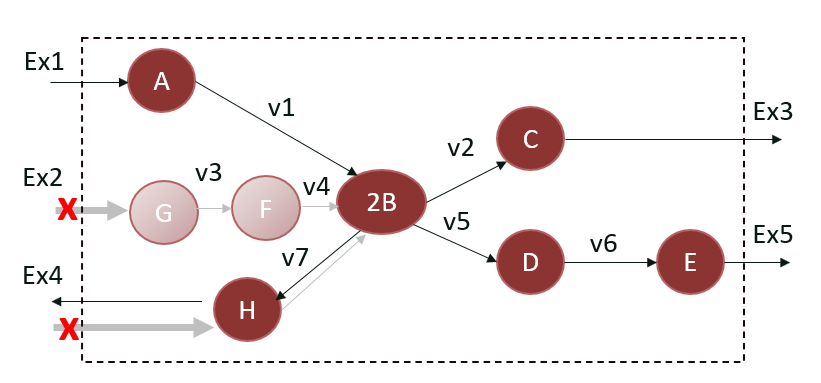

medium = {'A[c]'} % Create the medium containing only the metabolite 'A[c]'

medium = 1×1 cell array
    {'A[c]'}


[EX] = findExcRxns(model); % Find all exchange reactions
printRxnFormula(model, model.rxns(find(EX))); % Shows all exchange reactions

Ex1	A[c] 	<=>	
Ex2	G[c] 	<=>	
Ex3	C[c] 	->	
Ex4	H[c] 	<=>	
Ex5	E[c] 	->	


[~, rxnid] = find(model.S(ismember(model.mets, medium),:));
[Ex_open] = model.rxns(rxnid)

Ex_open = 2×1 cell array
    {'v1' }
    {'Ex1'}


Ex_to_close=setdiff(model.rxns(EX),Ex_open) % Find the reactions that should be unable to carry a flux

Ex_to_close = 4×1 cell array
    {'Ex2'}
    {'Ex3'}
    {'Ex4'}
    {'Ex5'}


**For the 'classically defined' model **

medium_model = model; % Save in case of mistake

for i = 1:length(Ex_to_close) % For each reactions to close
     var = nonzeros(medium_model.S(:,ismember(medium_model.rxns,Ex_to_close(i)))); % Return +1 if the reaction is an import / -1 if it is an export
     if var > 0 % Import
         medium_model.ub(ismember(medium_model.rxns,Ex_to_close(i))) = 0; % Close the upper bound (cannot receive a flux anymore)
     else % if var < 0 (Export)
         medium_model.lb(ismember(medium_model.rxns,Ex_to_close(i))) = 0; % Close the lower bound (cannot send a flux)
     end
end

disp('boundaries') ; disp([medium_model.rxns num2cell(medium_model.lb) num2cell(medium_model.ub)]) % New Upper & Lower boundaries for each reactions

boundaries
    {'v1' }    {[    0]}    {[1000]}
    {'v2' }    {[    0]}    {[1000]}
    {'v3' }    {[    0]}    {[1000]}
    {'v4' }    {[    0]}    {[1000]}
    {'v5' }    {[    0]}    {[1000]}
    {'v6' }    {[    0]}    {[1000]}
    {'v7' }    {[-1000]}    {[1000]}
    {'Ex1'}    {[-1000]}    {[1000]}
    {'Ex2'}    {[    0]}    {[1000]}
    {'Ex3'}    {[    0]}    {[1000]}
    {'Ex4'}    {[    0]}    {[1000]}
    {'Ex5'}    {[    0]}    {[1000]}



**For the Recon3D-like model**

medium_model = model; % Save in case of mistake
medium_model.lb(ismember(medium_model.rxns,Ex_to_close)) = 0

medium_model = struct with fields:
           rxns: {12×1 cell}
              S: [8×12 double]
             lb: [12×1 double]
             ub: [12×1 double]
              c: [12×1 double]
           mets: {8×1 cell}
              b: [8×1 double]
          rules: {12×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [8×1 char]
     rxnGeneMat: [12×12 double]
       metNames: {8×1 cell}
     subSystems: {12×1 cell}
        grRules: {12×1 cell}
       rxnNames: {12×1 cell}
    description: 'recon'


Indeed, all exchange relations are defined as reversible exports, so blocking imports is achieved by closing the lower bound of each of these reactions. 

**/!\** This case is only valid in the case of a model where the exchange relationships are defined in the Recon3D way. The general case is described above 

% Create a consistent model constrained by the metabolites present in the model 
A = fastcc_4_rfastcormics(medium_model, 1e-4, 0);

Optimal solution found.

Elapsed time is 0.007633 seconds.


medium_constrained_consistent_model=removeRxns(medium_model,medium_model.rxns(setdiff(1:numel(medium_model.rxns),A)))

medium_constrained_consistent_model = struct with fields:
           rxns: {9×1 cell}
              S: [6×9 double]
             lb: [9×1 double]
             ub: [9×1 double]
              c: [9×1 double]
           mets: {6×1 cell}
              b: [6×1 double]
          rules: {9×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [6×1 char]
     rxnGeneMat: [9×12 double]
       metNames: {6×1 cell}
     subSystems: {9×1 cell}
        grRules: {9×1 cell}
       rxnNames: {9×1 cell}
    description: 'recon'


% (Facultative) Visualize Model

disp('S') ; full(medium_constrained_consistent_model.S) %S Matrix

S


ans =     -1     0     0     0     0    -1     0     0     0
     2    -2    -2     0     2     0     0     0     0
     0     1     0     0     0     0    -1     0     0
     0     0     1    -1     0     0     0     0     0
     0     0     0     1     0     0     0     0    -1
     0     0     0     0    -1     0     0    -1     0


disp('mets') ; medium_constrained_consistent_model.mets %Metabolites 

mets


ans = 6×1 cell array
    {'A[c]'}
    {'B[c]'}
    {'C[c]'}
    {'D[c]'}
    {'E[c]'}
    {'H[c]'}


disp('rxns') ; medium_constrained_consistent_model.rxns %Reactions

rxns


ans = 9×1 cell array
    {'v1' }
    {'v2' }
    {'v5' }
    {'v6' }
    {'v7' }
    {'Ex1'}
    {'Ex3'}
    {'Ex4'}
    {'Ex5'}


disp('boundaries') ; disp([medium_constrained_consistent_model.rxns num2cell(medium_constrained_consistent_model.lb) num2cell(medium_constrained_consistent_model.ub)]) %Upper & Lower boundaries for each reactions

boundaries
    {'v1' }    {[    0]}    {[1000]}
    {'v2' }    {[    0]}    {[1000]}
    {'v5' }    {[    0]}    {[1000]}
    {'v6' }    {[    0]}    {[1000]}
    {'v7' }    {[-1000]}    {[1000]}
    {'Ex1'}    {[-1000]}    {[1000]}
    {'Ex3'}    {[    0]}    {[1000]}
    {'Ex4'}    {[    0]}    {[1000]}
    {'Ex5'}    {[    0]}    {[1000]}



disp('genes') ; disp(medium_constrained_consistent_model.genes)

genes
    {'Gene1'  }
    {'Gene2'  }
    {'Gene3'  }
    {'Gene4'  }
    {'Gene5'  }
    {'Gene6'  }
    {'Gene7'  }
    {'GeneEx1'}
    {'GeneEx2'}
    {'GeneEx3'}
    {'GeneEx4'}
    {'GeneEx5'}



printRxnFormula(medium_constrained_consistent_model)

v1	A[c] 	->	2 B[c] 
v2	2 B[c] 	->	C[c] 
v5	2 B[c] 	->	D[c] 
v6	D[c] 	->	E[c] 
v7	H[c] 	<=>	2 B[c] 
Ex1	A[c] 	<=>	
Ex3	C[c] 	->	
Ex4	H[c] 	->	
Ex5	E[c] 	->	


ans = 9×1 cell array
    {'A[c]  -> 2 B[c] ' }
    {'2 B[c]  -> C[c] ' }
    {'2 B[c]  -> D[c] ' }
    {'D[c]  -> E[c] '   }
    {'H[c]  <=> 2 B[c] '}
    {'A[c]  <=> '       }
    {'C[c]  -> '        }
    {'H[c]  -> '        }
    {'E[c]  -> '        }


**Consistent model after adding the condition on the medium : **

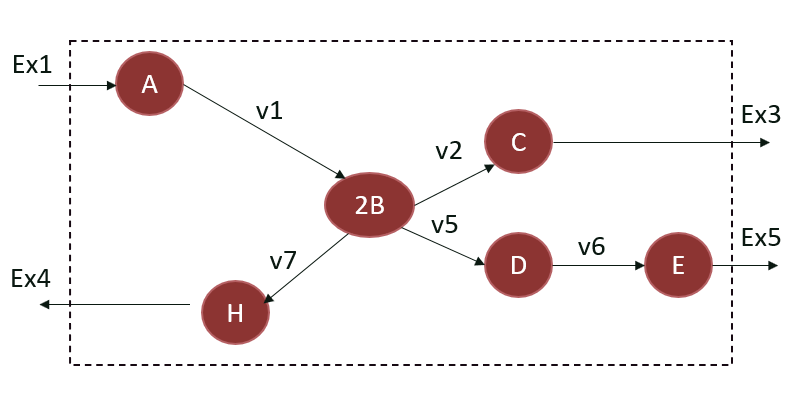

#### Introduction to Fastcormics : Integration of core reactions

• A **Core reactions** correspond to reactions supported by the data are forced to carry a flux above epsilon (small positive value) by an approximation of the cardinality function

• **Non Core reactions**: the inclusion of reactions not supported by the data is minimized by a L1-regularization (the inclusion on non-core reactions is penalized so that only non core reactions that are required to allow core reactions to be consistent are included)

In this example :

- Core reactions (*forced to carry a flux*) : **Ex3, v7**

- Inactive reaction (*do not carry a flux*) :  **v2**

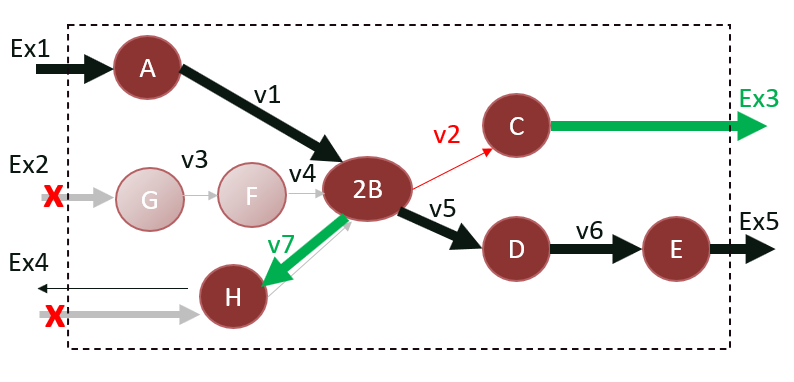

**Using Fastcormics : **

fastcormics_RNAseq(model, data, rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optinal_settings)

- **model **: Model use to extract the context-specific model from

- **data** : Matrix with *n* rows (1 per rxns) and *m* columns (1 per sample) with 1 for expressed genes, 0 for unknown expression and -1 for unexpressed genes. 

- **rownames** : The gene names for each row in the data

- **dico** :  Dictionary to map the gene names to the gene names in the model (e.g. Entrez to EnsemblID)

- **biomass_rxn **: Rxn that is (*generally*) to be maximized

- **already_mapped_tag** :  0 if the data has not been mapped to the GPR rules of the model, 1 otherwise

- **consensus_proportion** :  In the case where several samples are used to reconstruct a model

- **epsilon** :  Flux threshold value (1e-4)

- **optional_settings **: Structure containing 4 elements.

**Optional_settings : **

- **unpenalized** : Matrix containing the rxns that should not be penalized during model creation. These reactions are chosen above the others, even though they are not part of the core reactions. 

- **func** : Rxns that are (*generally*) to be maximized and must be retained

- **not_medium_constrained** : Rxns not included in the medium that must be retained

- **medium** : Metabolites present in the medium

discritized = [0;-1;0;0;0;0;1;0;0;1;0;0]; % For this model, we create a matrix based on the information in the description.

medium_constrained_consistent_model = struct with fields:
           rxns: {9×1 cell}
              S: [6×9 double]
             lb: [9×1 double]
             ub: [9×1 double]
              c: [9×1 double]
           mets: {6×1 cell}
              b: [6×1 double]
          rules: {9×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [6×1 char]
     rxnGeneMat: [9×12 double]
       metNames: {6×1 cell}
     subSystems: {9×1 cell}
        grRules: {9×1 cell}
       rxnNames: {9×1 cell}
    description: 'recon'


rownames = medium_constrained_consistent_model.genes;
dico = table(medium_constrained_consistent_model.genes, medium_constrained_consistent_model.genes);
biomass_rxn = 'Ex5'; % In this example we want to maximize 'Ex5'
already_mapped_tag = 0;
consensus_proportion = 1;
epsilon = 1e-4;

creating model.rev
unnesting subsystems
12 of 12 genes matched


Optimal solution found.


Optimal solution found.

Elapsed time is 0.017915 seconds.

Optimal solution found.


Optimal solution found.


Optimal solution found.



medium_core_constrained_consistent_model = struct with fields:
           rxns: {7×1 cell}
              S: [5×7 double]
             lb: [7×1 double]
             ub: [7×1 double]
              c: [7×1 double]
           mets: {5×1 cell}
              b: [5×1 double]
          rules: {7×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [5×1 char]
     rxnGeneMat: [7×12 double]
       metNames: {5×1 cell}
     subSystems: {7×1 cell}
        grRules: {7×1 cell}
       rxnNames: {7×1 cell}
    description: 'recon'
            rev: [7×1 double]


% Optional settings 
optional_settings = struct;
optional_settings.unpenalized = {};
optional_settings.func = {'Ex5'};
optional_settings.not_medium_constrained = {};
medium_constrained_consistent_model.description = 'recon'

S


ans =     -1     0     0     0    -1     0     0
     2    -2     0     2     0     0     0
     0     1    -1     0     0     0     0
     0     0     1     0     0     0    -1
     0     0     0    -1     0    -1     0


% optional_settings.medium = medium; % ERROR metFormulas

mets


ans = 5×1 cell array
    {'A[c]'}
    {'B[c]'}
    {'D[c]'}
    {'E[c]'}
    {'H[c]'}


rxns


ans = 7×1 cell array
    {'v1' }
    {'v5' }
    {'v6' }
    {'v7' }
    {'Ex1'}
    {'Ex4'}
    {'Ex5'}


boundaries
    {'v1' }    {[    0]}    {[1000]}
    {'v5' }    {[    0]}    {[1000]}
    {'v6' }    {[    0]}    {[1000]}
    {'v7' }    {[-1000]}    {[1000]}
    {'Ex1'}    {[-1000]}    {[1000]}
    {'Ex4'}    {[    0]}    {[1000]}
    {'Ex5'}    {[    0]}    {[1000]}



genes
    {'Gene1'  }
    {'Gene2'  }
    {'Gene3'  }
    {'Gene4'  }
    {'Gene5'  }
    {'Gene6'  }
    {'Gene7'  }
    {'GeneEx1'}
    {'GeneEx2'}
    {'GeneEx3'}
    {'GeneEx4'}
    {'GeneEx5'}



#### Creation of the 'Medium & Core Constrained Consistent Model' 

To create a model from the A_final array, we will create a logical matrix with the samples as columns and the reactions as rows in which 1 depicts if a reaction should take place in the context-specific model.

% run Fastcormics_RNAseq 

v1	A[c] 	->	2 B[c] 
v5	2 B[c] 	->	D[c] 
v6	D[c] 	->	E[c] 
v7	H[c] 	<=>	2 B[c] 
Ex1	A[c] 	<=>	
Ex4	H[c] 	->	
Ex5	E[c] 	->	


ans = 7×1 cell array
    {'A[c]  -> 2 B[c] ' }
    {'2 B[c]  -> D[c] ' }
    {'D[c]  -> E[c] '   }
    {'H[c]  <=> 2 B[c] '}
    {'A[c]  <=> '       }
    {'H[c]  -> '        }
    {'E[c]  -> '        }


[medium_core_constrained_consistent_model, ~] = fastcormics_RNAseq(medium_constrained_consistent_model, discritized, rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings)

**Medium & Core Constrained Consistent Model : **

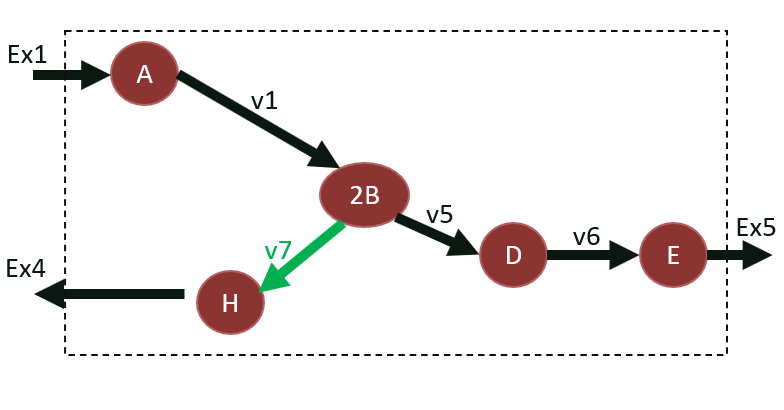

% (Facultative) Visualize Model

disp('S') ; full(medium_core_constrained_consistent_model.S) %S Matrix

summaryT = 1×5 table
    Coefficient    Metabolite    metID    Reaction    RxnID
    ___________    __________    _____    ________    _____

        -1            E[c]         4        Ex5         7  


ans = 1×1 cell array
    {'Ex5'}


disp('mets') ; medium_core_constrained_consistent_model.mets %Metabolites 
disp('rxns') ; medium_core_constrained_consistent_model.rxns %Reactions
disp('boundaries') ; disp([medium_core_constrained_consistent_model.rxns num2cell(medium_core_constrained_consistent_model.lb) num2cell(medium_core_constrained_consistent_model.ub)]) %Upper & Lower boundaries for each reactions


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2020b.


disp('genes') ; disp(medium_core_constrained_consistent_model.genes)

solution = struct with fields:
    origStatText: 'Optimal solution found'
               f: 1000
              f0: NaN
              f1: 1000
              f2: NaN
               v: [7×1 double]
               y: [5×1 double]
               w: [7×1 double]
               s: [5×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
            time: 0.0070
           basis: [1×1 struct]
          vars_v: []
               x: [7×1 double]


printRxnFormula(medium_core_constrained_consistent_model)

#### Objective and optimisation of the Model

We set an objective function in the model. In this example we have decided to maximize the rxn 'Ex5'

index_objective_rxn = find(ismember(medium_core_constrained_consistent_model.rxns, 'Ex5')); % Find the index of the 'Ex5' rxn
medium_core_constrained_consistent_model = changeObjective(medium_core_constrained_consistent_model,medium_core_constrained_consistent_model.rxns(index_objective_rxn)); % Change the objective function 
printObjective(medium_core_constrained_consistent_model) % Check the change 

We can now optimize the model to get the maximal value through the 'v5' rxn.

changeCobraSolver('ibm_cplex');
solution = optimizeCbModel(medium_core_constrained_consistent_model,'max') 

The solution.f field give the maximal value of the flux through the objective function. 